# Kindleのスクショを自動で行う闇のMATLAB術

## 01. はじめに

### **背景**

自分は Kindle ヘビーユーザだが最近 iPad 導入に伴って、Goodnotes を使うようになった。

そこで Kindle の書籍に直接書き込めるようにしたいと思い今回の MATLAB 術を考えた。

**※注意！**

これはあくまで自己責任でのご使用をお願いします。

また利用規約等をしっかり確認し私的利用にとどめてください。

参考：[Kindleのスクショを撮る際の法的リスクと利用ガイド:2024年版](https://note.com/dr_harv/n/nfe4c86511728)

## 02. 初期設定

### 初期化 & サブモジュール追加

clc,clear,close all;
addpath functions

### ユーザーの選択

[MATLAB Answers](https://jp.mathworks.com/matlabcentral/answers/269214-how-to-get-the-account-username-using-matlab#answer_210626) を見ると [getenv](https://jp.mathworks.com/help/matlab/ref/getenv.html) を使うといいらしい( Windows 環境限定)。

Username = getenv('USERPROFILE');

### 画像フォルダとPDF用フォルダを設定

inputDir はスクショした画像を保存する場所で OutputDir は pdf 形式に変換したものを保存する場所である。

inputDir = "tmp";
OutputDir = "Out";
folderName = [inputDir; OutputDir];
for ii = 1:length(folderName)
    if ~exist(folderName(ii), 'dir')
        mkdir(folderName(ii));
    end
end

## 03. Kindleの起動

Kindle.exeからアプリを起動する。ここでKindleで魚拓をとる書籍を選ぶ。

**※アプリが立ち上がるのを待つ必要があるが、久々に開くと5秒じゃ足りないので注意**

% パスの設定
Path_Kindle = fullfile(Username,'\AppData\Local\Amazon\Kindle\application','Kindle.exe');
txt = ['start "" ',Path_Kindle];

% Kindleを起動
system(txt);
% アプリケーション起動待機
pause(5);

## 04. 対象のモニター確認

スクリーンショットするにあたって、モニターが２つ以上ある場合は選択する必要がある。

メジャーな方法としてはマウスの座標とスクリーンの座標を照らし合わせる方法がある。

これだと直感的にわからないので今回は実際に全画面のスクショをとって確認する。

### モニターの番号を入力

ここではサンプルとして自分が使っているモニター2をスクショしていく。

マルチモニターでなければ 1 で良い。

monitorNumber = 2;

### 描写して確認

実際にはメッセージボックスしか出てないように見えるが、スクショの画面も表示されている。

メッセージボックスを閉じると画面も閉じられる。

% 描写
imgData = ScreenCap(monitorNumber);

% 確認
figure
set(gcf,'Visible','on')
drawFigure(imgData)
uiwait(msgbox(sprintf('This is monitorNumber = %i',round(monitorNumber))));
close

## 05. スクショ範囲決定

Kindle のスクショする範囲を指定する。

getpoints という自作関数でモニター番号を指定してクロップする範囲を GUI で決定することができる。

**※kindleは最大化してスクショをとるので最大化しておいてください**

pos = getpoints(monitorNumber);

起動すると以下のメッセージが出るのでOKを押す。

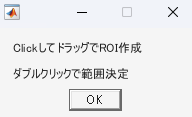

範囲を確認する。

fprintf("範囲\n[xmin: %d, ymin: %d, width: %d, height: %d]", ...
    round(pos(1)),round(pos(2)),round(pos(3)),round(pos(4)))

範囲
[xmin: 530, ymin: 95, width: 911, height: 906]

## 06. クロップ範囲を簡易的に確認

数字だけだとわからないので切り抜き範囲を確認する。

imgData     = ScreenCap(monitorNumber);
imgData_c   = imcrop(imgData,pos);
figure
set(gcf,'Visible','on')
drawFigure(imgData_c)
uiwait(msgbox(sprintf("切り抜き範囲\n[xmin: %d, ymin: %d, width: %d, height: %d]", ...
    round(pos(1)),round(pos(2)),round(pos(3)),round(pos(4)))));
close

## 06. めくる番号と方向を決める

何ページめくるかをここで確認する。

また書籍によっては左にめくるか右にめくるか決める必要がある。

自作関数 InitialSet を用いて GUI 形式に指定できる。

output = InitialSet;

指定されたページ番号: 5
選択された方向: 右


## 07. Kindle魚拓準備

もし Kindle を閉じていた場合は起動する。

% Kindleを起動する
system(txt);

Kindle の画面最大化を行う。

デュアルモニターのみに起きるバグ(？)だと思うがマウスを Kindle が存在するモニター上に置いていないとうまくいかない。

これはマウスが別のモニターをまたがって操作できないためと思われる。

robot = java.awt.Robot();
% マウス移動
robot.mouseMove(pos(1) + 50, pos(2) - 100);
% マウス左クリック
robot.mousePress(java.awt.event.InputEvent.BUTTON1_MASK);
robot.mouseRelease(java.awt.event.InputEvent.BUTTON1_MASK);
pause(.5)

robot.keyPress(java.awt.event.KeyEvent.VK_F11);
robot.keyRelease(java.awt.event.KeyEvent.VK_F11);

pause(.5)
robot.keyPress(java.awt.event.KeyEvent.VK_ALT);
robot.keyPress(java.awt.event.KeyEvent.VK_TAB);
robot.keyRelease(java.awt.event.KeyEvent.VK_ALT);
robot.keyRelease(java.awt.event.KeyEvent.VK_TAB);

## 08. Kindle魚拓開始

ここではマウスを自動でポチポチさせながらスクショを繰り返す。

ステップ07と同様にマウスを Kindle が開かれている画面に置いておくこと。

またこのステップ中はマウスを動かしてはいけない。

robot = java.awt.Robot();

% マウス移動
robot.mouseMove(pos(1) + 50, pos(2) - 100);
% マウス左クリック
robot.mousePress(java.awt.event.InputEvent.BUTTON1_MASK);
robot.mouseRelease(java.awt.event.InputEvent.BUTTON1_MASK);
pause(.5)

for ii = 1:output.pageNumber
    pause(.5)
    I = ScreenCap(monitorNumber);
    I = imcrop(I,pos);
    imwrite(I,fullfile("tmp", sprintf('out_%03d.tif',round(ii))),'tif')
    SlideControl(robot,output.direction)
end

uiwait(msgbox("おわり"))
pause(.5)
robot.keyPress(java.awt.event.KeyEvent.VK_ALT);
robot.keyPress(java.awt.event.KeyEvent.VK_TAB);
robot.keyRelease(java.awt.event.KeyEvent.VK_ALT);
robot.keyRelease(java.awt.event.KeyEvent.VK_TAB);

スクショが終わると以下のメッセージボックスが表示される。

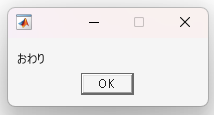

## 09. 画像をpdf形式へ変換

このままだと画像になっているのでpdfへ変換する。

OCR 等を適用させるためにサードパーティツールを使う場合は inputDir の画像を png 形式にして読み込ませる。

% inputDir : 画像ファイルが保存されているディレクトリのパス
outputFile = fullfile(OutputDir,'output.pdf');  % 出力するPDFファイルの名前を指定

% ディレクトリ内のすべての画像ファイルを取得
pngFiles = dir(fullfile(inputDir, '*.tif'));

% 新しいPDFファイルを作成し、画像を追加していく
resolution = 750;  % 解像度を300 DPIに設定

for k = 1:length(pngFiles)
    pngFile = fullfile(inputDir, pngFiles(k).name);
    img = imread(pngFile);

    figure('Visible', 'off');
    imshow(img);

    if k == 1
        exportgraphics(gca, outputFile, 'ContentType', 'image', 'Resolution', resolution, 'Append', false);
    else
        exportgraphics(gca, outputFile, 'ContentType', 'image', 'Resolution', resolution, 'Append', true);
    end
    close(gcf);
end

disp('PDFファイルが正常に作成されました。');

PDFファイルが正常に作成されました。


## 10. 画像フォルダ削除

画像ファイルは容量を圧迫するのでここで削除する。

if exist(folderName(1), 'dir')
    rmdir(folderName(1), 's'); % 's'オプションでフォルダ内のファイルも削除
    disp(strcat("フォルダ ", folderName(1), " を削除しました。"));
else
    disp(strcat("フォルダ ", folderName(1)," は存在しません。"));
end

フォルダ tmp を削除しました。


## 11. おわりに

結局、自分はこのスクリプトを動かしていない。

そもそも教科書に書き込みをあまりしないし、最近は [Obsidian](https://obsidian.md/) などでメモする程度だからだ。

Goodnotes は pdf 形式の論文を読むときに使うか、純粋にノート代わりに使用している。

そうなる時になった画像だけコピペすれば事足りてしまったのである。

後、勉強に使う書籍は最終的に紙の本買う…。